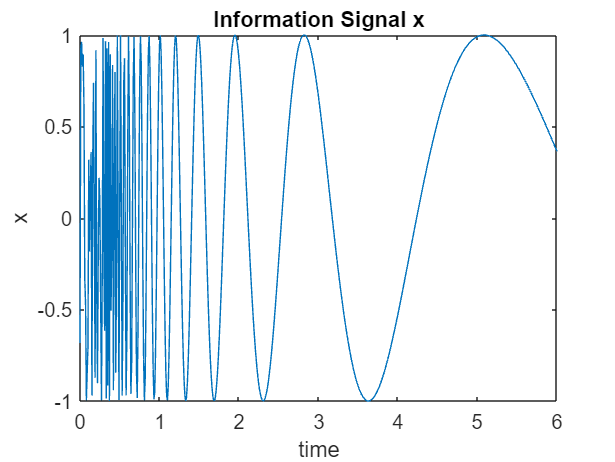

time = (0:0.01:6)';
x = sin(40./(time+0.01));
plot(time,x)
title('Information Signal x')
xlabel('time')
ylabel('x')

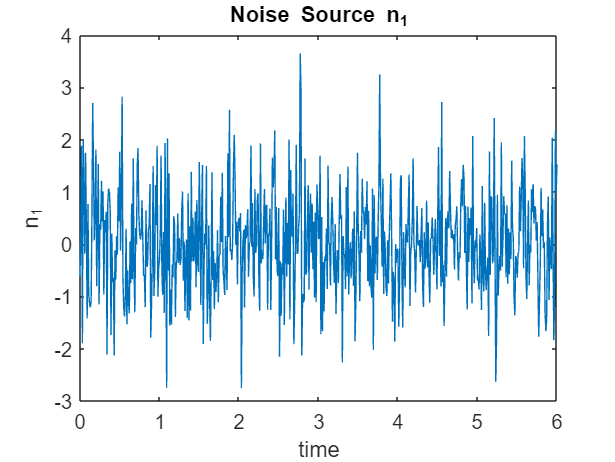

n1 = randn(size(time));
plot(time,n1)
title('Noise Source n_1')
xlabel('time')

ylabel('n_1')

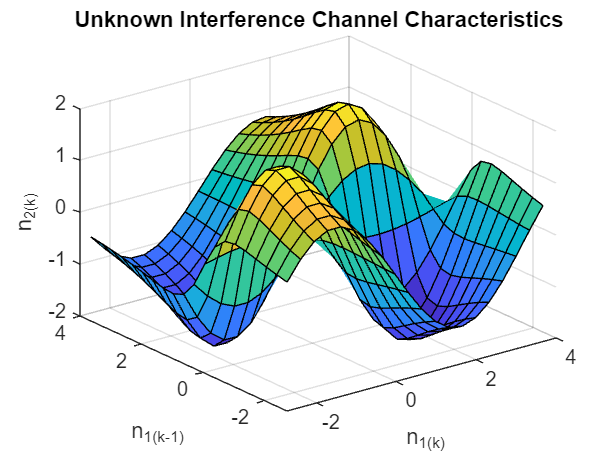

domain = linspace(min(n1),max(n1),20);
[xx,yy] = meshgrid(domain,domain);
zz = 4*sin(xx).*yy./(1+yy.^2);

surf(xx,yy,zz)
xlabel('n_1(k)')
ylabel('n_1(k-1)')
zlabel('n_2(k)')
title('Unknown Interference Channel Characteristics')

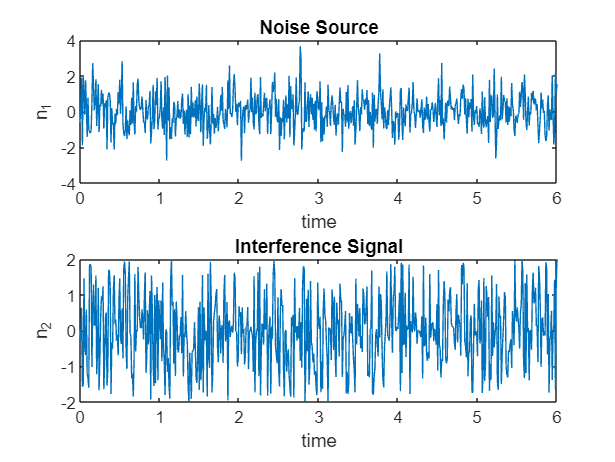

n1d0 = n1;                            % n1 with delay 0
n1d1 = [0; n1d0(1:length(n1d0)-1)];   % n1 with delay 1
n2 = 4*sin(n1d0).*n1d1./(1+n1d1.^2);  % interference

subplot(2,1,1)
plot(time,n1)
ylabel('n_1')
xlabel('time')
title('Noise Source')
subplot(2,1,2)
plot(time,n2)
ylabel('n_2')
title('Interference Signal')
xlabel('time')

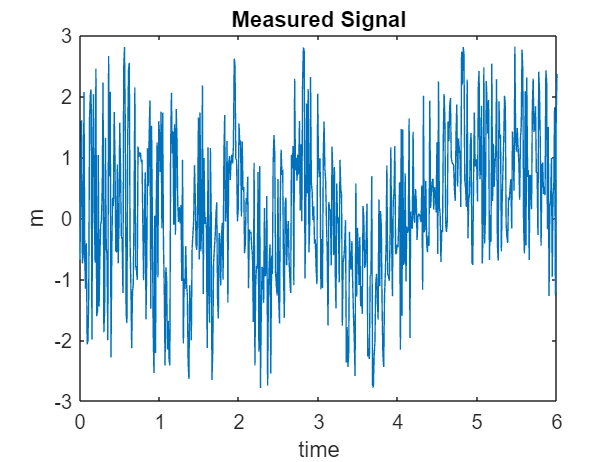

m = x + n2;
subplot(1,1,1)
plot(time, m)
title('Measured Signal')
xlabel('time')
ylabel('m')

delayed_n1 = [0; n1(1:length(n1)-1)];
data = [delayed_n1 n1 m];

genOpt = genfisOptions('GridPartition');
inFIS = genfis(data(:,1:end-1),data(:,end),genOpt);

trainOpt = anfisOptions('InitialFIS',inFIS,'InitialStepSize',0.2);
outFIS = anfis(data,trainOpt);

ANFIS info:
	Number of nodes: 21
	Number of linear parameters: 12
	Number of nonlinear parameters: 12
	Total number of parameters: 24
	Number of training data pairs: 601
	Number of checking data pairs: 0
	Number of fuzzy rules: 4


Start training ANFIS ...

1 	 0.780145
2 	 0.763906
3 	 0.750749
4 	 0.741297
Step size increases to 0.220000 after epoch 5.
5 	 0.735253
6 	 0.730311
7 	 0.725544
8 	 0.721424
Step size increases to 0.242000 after epoch 9.
9 	 0.718708
10 	 0.720133

Designated epoch number reached. ANFIS training completed at epoch 10.

Minimal training RMSE = 0.718708


estimated_n2 = evalfis(outFIS,data(:,1:2));

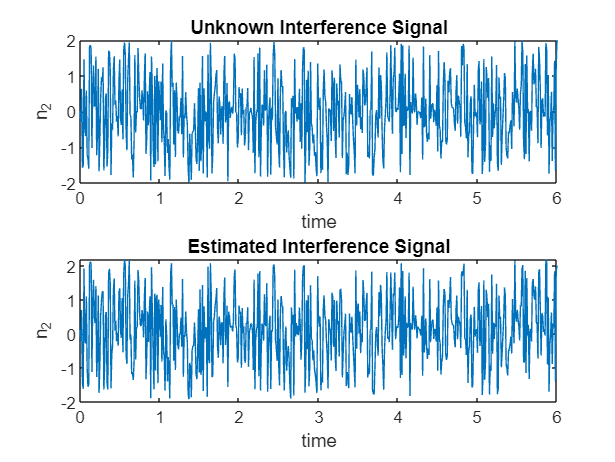

subplot(2,1,1)
plot(time, n2)
ylabel('n_2')
xlabel('time')
title('Unknown Interference Signal')
subplot(2,1,2)
plot(time, estimated_n2)
ylabel('n_2')
xlabel('time')
title('Estimated Interference Signal')

estimated_x = m - estimated_n2;

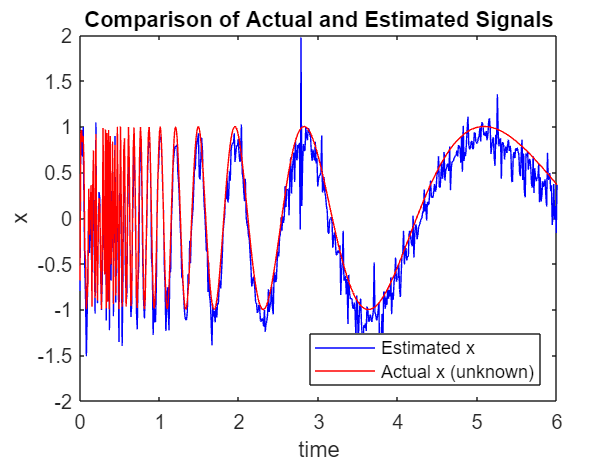

figure
plot(time,estimated_x,'b',time,x,'r')
xlabel('time')
ylabel('x')
title('Comparison of Actual and Estimated Signals')
legend('Estimated x','Actual x (unknown)','Location','SouthEast')